# 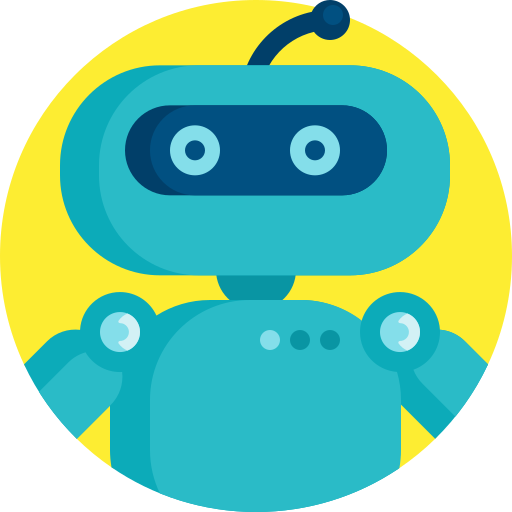

# **MEC4127F: Introduction to Robotics**

# Chapter 1: Introduction

## 1.1 Introduction

This course will introduce you to the wonderful world of robotics. The content in this course is set such that an undergraduate exit-level understanding of the various building blocks of robotics can be developed. The content is quantitative in nature and will enable you to approach robotic-based problems with a systematic and analytic mindset. The mathematical skills developed in the lectures will then be applied to simulated and practical robotic systems, thereby bridging the gap between robotic theory and application. This will be facilitated using a subset of MATLAB's toolboxes, which will involve the robotic design, analysis, simulation stages, and introductory state estimation and control design

Robotics is a large field of engineering and we, unfortunately, do not have the time or resources to explore everything it contains. We will instead cover some generalised concepts that can be applied to a range of robotic platforms, and also narrow our scope to a three robotic systems. The three simplified platforms — a differentially-steered robot, a two-link manipulator, and a quadcopter — serve as appealing entry-level systems to build on in subsequent robotic engagement, be it in a final-year project or MSc/PhD.

More advanced techniques are alluded to in the notes as an invitation for future engagement, be it in a final-yearend project or postgraduate career. If you have interest in pursuing any of these topics, please feel free to contact me.

These notes make extensive use of concepts, derivations, and explanations delivered in the textbooks listed below, and may serve well as supplementary reading (although this is not mandatory). 

- **Robotics, Vision and Control**, by Peter Corke,

- **Modern Robotics**, by Kevin Lynch and Frank Parkl,

- **Springer Handbook of Robotics**, by Bruno Siciliano and Oussama Khatib,

- **Robotics: Modelling, Planning and Control**, by Bruno Siciliano, Lorenzo Sciavicco, Luigi Villani, and Giuseppe Oriolo.

## 1.2 MATLAB Live Scripts

These course notes have been written in `MATLAB Live Scripts` and comprise text, LaTeX equations, imagery, and mathematical development, as well as code that is used to generate a variety of useful visualisations. The intention is that you play around with the provided code to get a better understanding of the various concepts that we will cover.

### 1.2.1 Using live scripts

The live scripts have been *sectioned off* (indicated by the thin blue horizontal lines such as just before Section 1.2.2) so that you can run code on a section by section basis. You can use `Run Section `using CMD+ENTER (macOS) or CTRL+ENTER (Windows), or using the `Run Section` button under the `LIVE EDITOR banner `at the top of your screen.

If you want to view the code, select the `Output inline `(figures appear below the text) or `Output on right `(figures appear on the right of the script) button on the top right of the script (see image below). Otherwise, select `Hide code`.

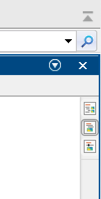

**Figure 1.1:** Live script view options, found at the top right corner of the script: Output on right (top button), Output inline (middle button), Hide code (bottom button).

You can zoom in/out in `MATLAB live scripts` using CMD+scroll (macOS) or CTRL+scroll (Windows). You can also zoom using the buttons under the `VIEW` banner at the top of the screen. Zooming may help if text/images are too big or small on your monitor.

### 1.2.2 `MATLAB` code blocks

An example of a `MATLAB` code block is shown below. Code blocks will typically consist of parameters that you can change to observe how this affects some kind of visual response (in this case there are numerical sliders that you can play around with). Note that when you alter the slider, all the code blocks within the section will run automatically. You are also welcome to change other parts of the code as part of your experimentation!

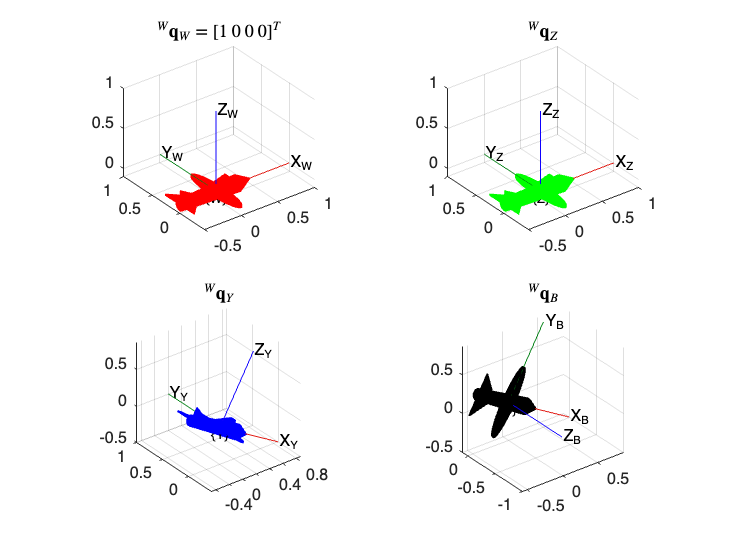

phi = 90*pi/180;    %set roll angle
the = 30*pi/180;    %set pitch angle
psi = 0*pi/180;    %set yaw angle

q_z2w = [cos(psi/2) 0 0 sin(psi/2)];    %quaternion equivalent of yaw
q_y2z = [cos(the/2) 0 sin(the/2) 0];    %quaternion equivalent of pitch
q_b2y = [cos(phi/2) sin(phi/2) 0 0];    %quaternion equivalent of roll

q_b2w = quatmultiply( quatmultiply(q_z2w,q_y2z), q_b2y );    %quaternion description of full orientation

%plot figures
figure,hold on
subplot(2,2,1),plotTransforms([0 0 0],[1 0 0 0],"MeshFilePath",'fixedwing.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","W")
axis equal, title('$^W{\bf q}_W=[1~0~0~0]^T$',Interpreter='latex'),grid on
subplot(2,2,2),plotTransforms([0 0 0],q_z2w,"MeshFilePath",'fixedwing.stl',"MeshColor","green","FrameAxisLabels","on","FrameLabel","Z")
axis equal, title('$^W{\bf q}_Z$',Interpreter='latex'),grid on
subplot(2,2,3),plotTransforms([0 0 0],quatmultiply(q_z2w,q_y2z),"MeshFilePath",'fixedwing.stl',"MeshColor","blue","FrameAxisLabels","on","FrameLabel","Y")
axis equal, title('$^W{\bf q}_Y$',Interpreter='latex'),grid on
subplot(2,2,4),plotTransforms([0 0 0],quatmultiply( quatmultiply(q_z2w,q_y2z),q_b2y),"MeshFilePath",'fixedwing.stl',"MeshColor","black","FrameAxisLabels","on","FrameLabel","B")
axis equal, title('$^W{\bf q}_B$',Interpreter='latex'),grid on

You are not expected to understand the code above just yet, but hopefully in a few weeks this will make some sense to you! Note that you can find more information about *any* `MATLAB` function by using the `help` function, for example:

%Example
help quatmultiply

 quatmultiply - Calculate product of two quaternions
    This MATLAB function calculates the quaternion product, quatprod, for
    two quaternions, q and r.

    Syntax
      quatprod = quatmultiply(q,r)

    Input Arguments
      q - First quaternion
        m-by-4 matrix | 1-by-4 quaternion | real
      r - Second quaternion
        m-by-4 matrix | 1-by-4 quaternion | real

    Output Arguments
      quatprod - Output quaternion product
        m-by-4 matrix

    Examples
      Determine t

## 1.3 Main challenges of autonomous robots

Given an arbitrarily defined task, the primary challenges (and by extension, dominant research spheres) in autonomous robotics can be summarised as:

- **Mathematical modelling:** $\textit{What kind of robot is this, what are the physical limitations, and how do we expect it to behave?}$

- **State estimation:** $\textit{How do we gather and integrate information in order to determine where it is and how it is actually behaving?}$

- **Path planning and trajectory generation:** $\textit{How should we best command the robot to move given the predefined task?}$

- **Control design:** $\textit{How does the robot incorporate all the aforementioned information to achieve our requested task under uncertain/unfavourable conditions?}$

These concepts are all fundamentally linked and a systematic approach is required in order to answer these questions appropriately and arrive at a viable solution. By not attempting to understand the underlying questions, the design process collapses into an inefficient trial-by-error process. We cannot expect our robotic platform to perform dynamically infeasible manoeuvres or operate on poor or misleading sensor information. Similarly, we can only apply limited amounts of energy to our robot, so there is an inherent limit to what is achievable on any given platform. This course will touch on all of the aforementioned disciplines to some extent, with the hope that a holistic view of a robotic system's overarching functionality can be developed.

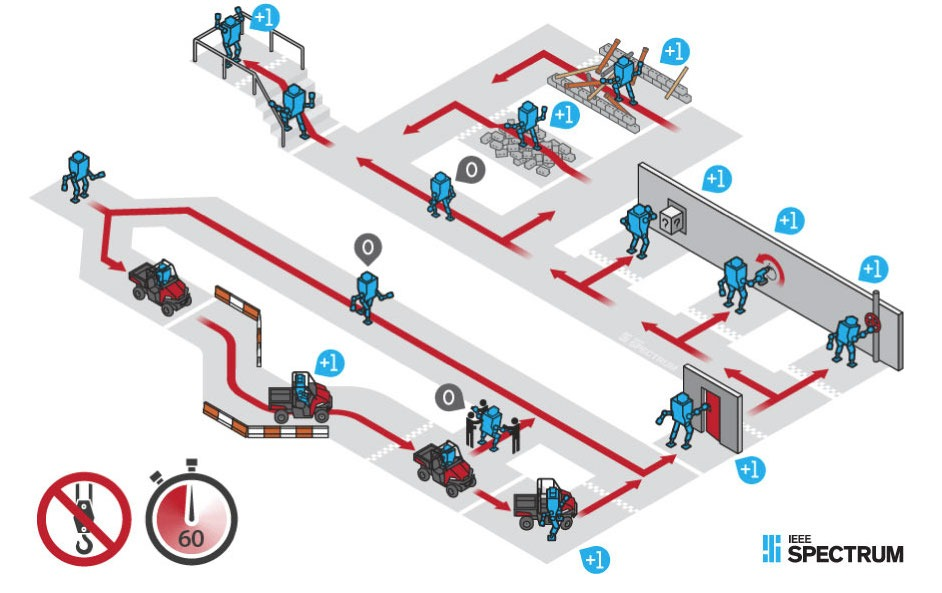

**Figure 1.2:** Visual description of the high-level tasks required in the US Defense Advanced Research Projects Agency (DARPA) 2015 finals [[1]](https://robohub.org/darpas-robotics-challenge-a-pocket-sized-guide-to-the-finals/)

## 1.4 Platforms under consideration

Robotics is a rapidly evolving field of research that considers a wide range of different robotic platforms and applications. As such, there is not enough time in this course to cover all types of robotic platforms. Instead, we will focus on three popular mobile robotic platforms that have powerful real-world uses. Mobile robots can be distinguished from other robots by their ability to move autonomously, with sufficient intelligence to react and make decisions based on the perception they receive from the environment. Mobile robots can be grouped into different sub-categories, with potential overlap depending on the hybrid nature of the platform. 

### 1.4.1 Manipulator arms

As humans, we often make use of our hands without conscious thought. Whether its typing, writing, or hammering a nail, there is an inherent dexterity and precision involved with any hand task. It is of no surprise that robotic intervention at the level of a hand-based task is appealing for a multitude of reasons. Robot manipulators (or arm-type robots) are a familiar sight in industrial assmebly lines. They commonly perform repetitive tasks such as assembly, welding, and package handling (to name a few). Manipulators often have a static base and operate within a limited workspace. In predictable environments, manipulators can be used to perform fast, high-precision manoeuvres, with consistency that cannot be rivaled by humans. A manipulator makes use of a combination of rotary (rotational motion) and/or prismatic (linear motion) joints in order to reach the required end-effector configuration. 

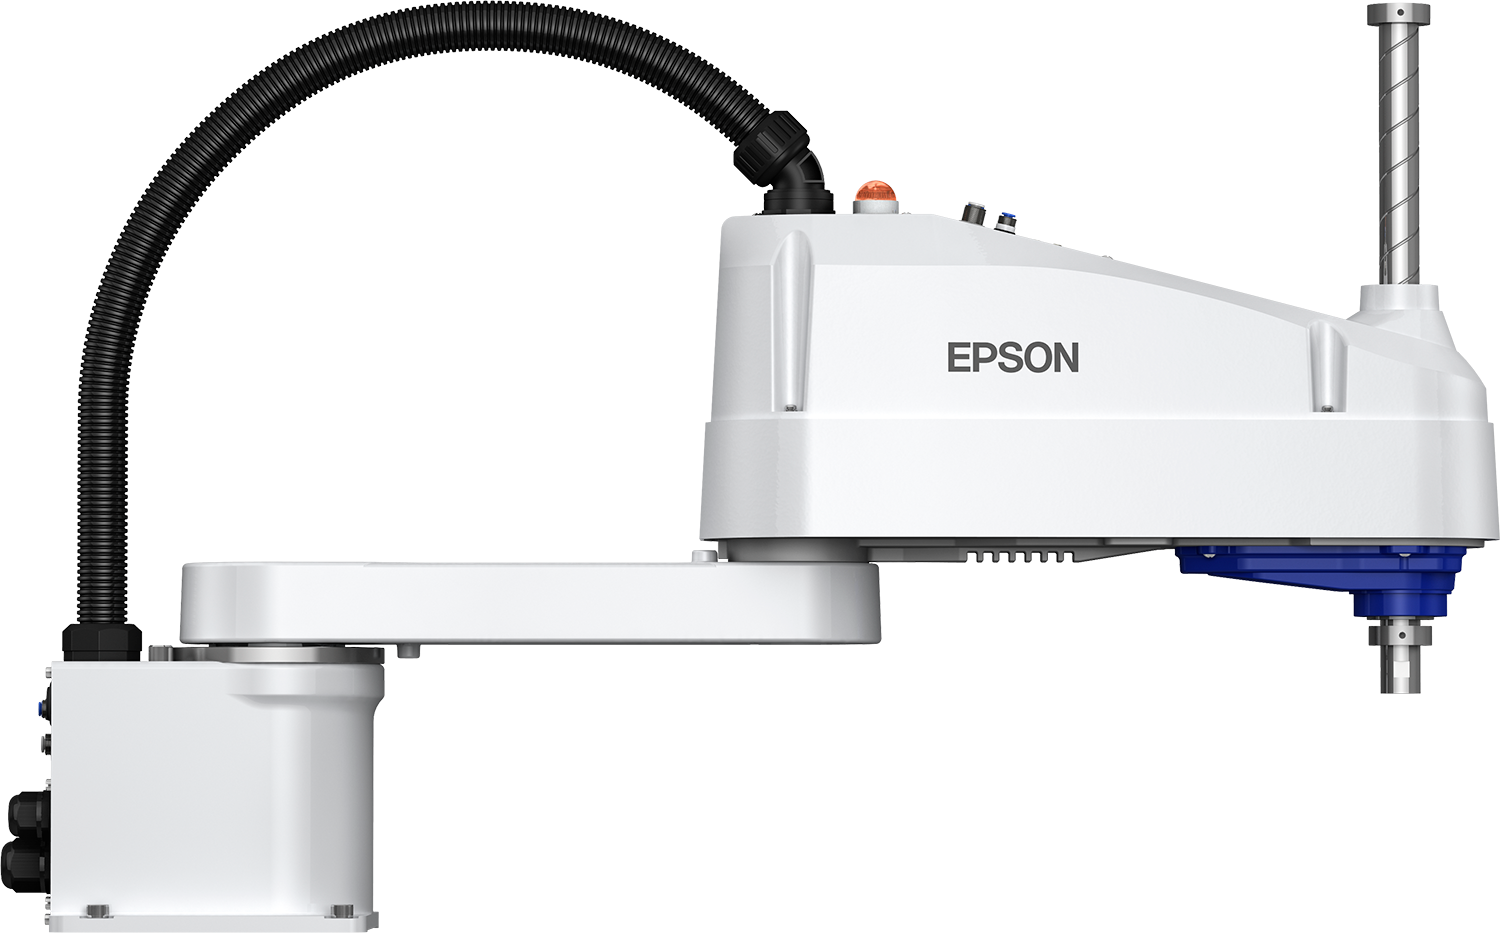

**Figure 1.3:** Side-view of a Selective Compliance Assembly Robot Arm (SCARA) robot from EPSON [[2]](https://robohub.org/darpas-robotics-challenge-a-pocket-sized-guide-to-the-finals/)

A simplified planar manipulator will be investigated in this module, which gives a taste of the interesting elements of an arm-type robot.

### 1.4.2 Wheeled robots

**Wheeled robots** (see [DARPA Challenge](https://www.youtube.com/watch?v=PhF3cbQRp2s)) are commonly chosen when tasks require locomotion on surfaces that are flat and easy to traverse. Rolling provides an appealing energy-speed ratio, making the invention of the wheel one of the greatest contributions to robotics and society in general! As a result, humans have altered and adjusted their environments in order to accommodate wheeled locomotion, such as the ever expanding road networks. By stark contrast, evolution has not elected to supply a single animal with a wheel-like actuator. We will investigate a specific type of wheeled robot in this module. Specifically, a differentially-steered robot. 

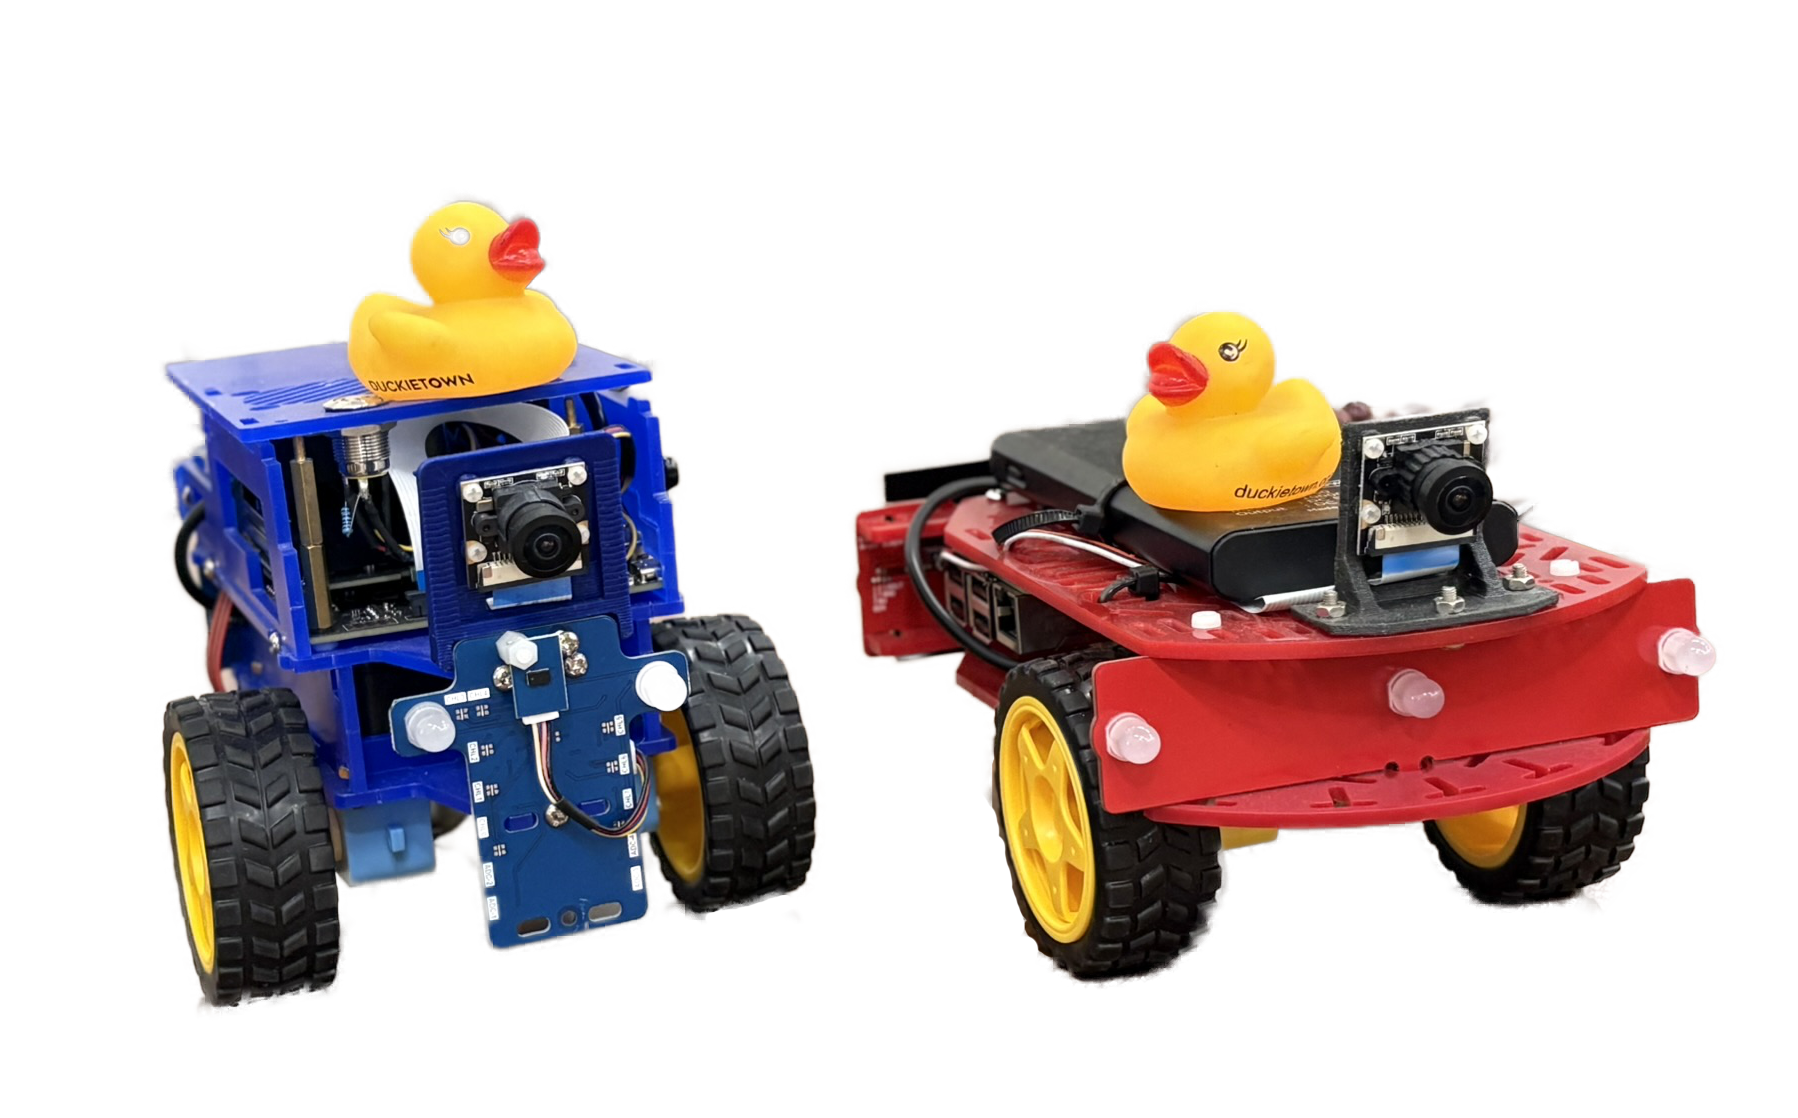

**Figure 1.4:** The DuckieBot, a differentially-steered robot that is used in the MechatronicSystems.Group for research

### 1.4.3 Aerial robots

**Aerial robots** (see [Deep Drone Acrobatics](https://www.youtube.com/watch?v=2N_wKXQ6MXA)) encapsulate a wide range of different mechanical configurations, such as multirotors (e.g. quadrotors), fixed-wing planes, tailsitters, and even hybrids. The specific type of robot will determine the degrees of freedom (DOF) that is inherent to the platform. For example, a car can only traverse on a 2D plane and adjust its heading, giving it 3 degrees of freedom. On the other hand, a quadrotor can adjust its 3D position and orientation at any time, thereby making it a 6 DOF system in theory. 

We will cover quadcopters in detail towards the tail-end of this course. The platform that we will experiment with is shown in Figure 1.5.

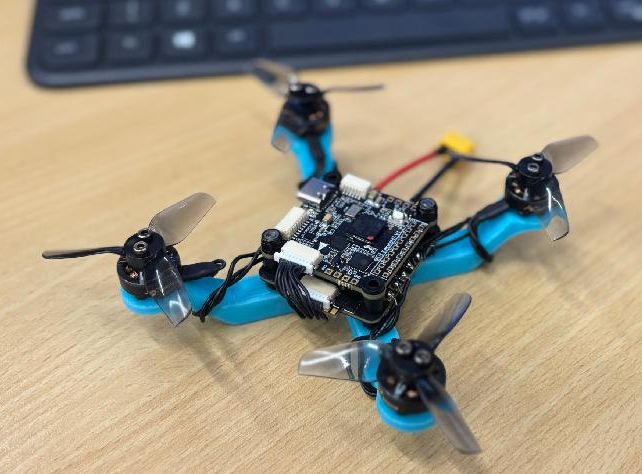

**Figure 1.5:** The micro-sized quadcopter that will be used in this course


## 1.5 Right-hand rule convention

It is common practice to use **right-hand rule** notation in robotics (and engineering in general) and these notes we will follow suit here. If textbooks and research articles do not indicate which notation is used, you can safely assume they are also using right-hand rule notation (though you can always easily check). As a reminder, we can use our right hand to emulate a coordinate system. With reference to Figure 1.6, our pointing finger indicates the $x$-axis direction, our middle finger, made to be perpendicular to our pointing finger, then describes the corresponding $y$-axis, and finally, our thumb, perpendicular to the pointing and middle finger, indicates the direction of our $z$-axis. Our right hand can also be used to emulate the rotational system. When curling the fingers of our right hand as shown below, our thumb indicates the positive direction for the axis in question, and the motion of curling the remaining digits towards the center of the palm indicates the positive rotational direction for that axis.

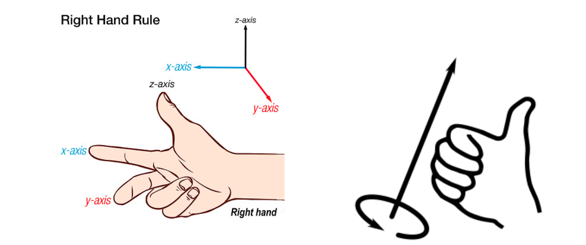

**Figure 1.6:** (Left) Right-hand rule coordinate convention [[3]](https://www.pasco.com/products/guides/%20right-hand-rule), (Right) Right-hand rule rotational convention [[4]](https://commons.wikimedia.org/wiki/File:Right_hand_%20rule_simple.png)

## 1.6 Chapters in this course

- **Chapter 1**: Introduction

- **Chapter 2**: Rigid-body motion

- **Chapter 3**: Orientation and angular velocity

- **Chapter 4**: Pose estimation

- **Chapter 5**: Trajectory generation

- **Chapter 6**: Forward and inverse kinematics of manipulators

- **Chapter 7**: Forward and inverse kinematics of wheeled robots

- **Chapter 8**: Control design for wheeled robots

- **Chapter 9**: Forward and inverse dynamics of multi-rotors

- **Chapter 10**: Control design for quadcopters